# Create a Real-Time Dashboard Using the Live Editor

In the Live Editor, you can create dashboards to display and analyze real-time data. When creating these dashboards, you can use buttons to retrieve and display real-time data on demand, and other interactive controls to modify the displayed data. To show only the formatted text, controls, and results to the dashboard user, hide the code.

This example shows how to create a simple weather dashboard in the Live Editor. The dashboard uses a button and a check box to get and display real-time weather data.

To view and interact with the weather dashboard, open this example in MATLAB®.

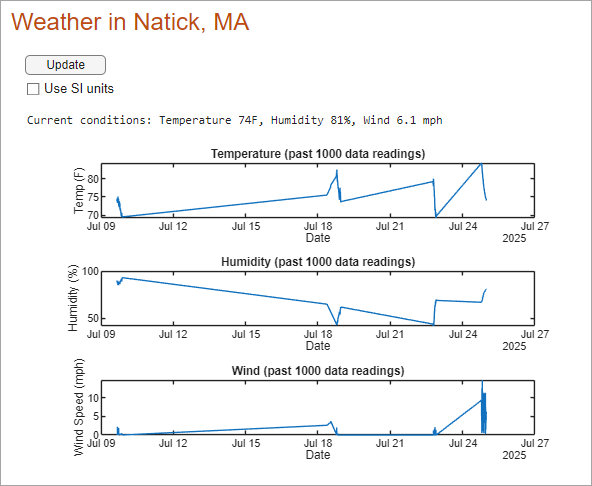

## Create the Dashboard

You can open a copy of the weather dashboard by opening this example in MATLAB. To recreate the dashboard yourself, create a live script named `WeatherDashboard.mlx`. Then, add the descriptive text and code, configure the controls, and hide the code.

### Add the Code

Copy the descriptive text and code in the Code for Weather Dashboard section to get and display real-time data from ThingSpeak™ channel 12397. This channel collects weather data from an Arduino-based weather station in Natick, Massachusetts.

### Configure the Controls

The dashboard uses a button to update the displayed weather data and a check box to toggle the units used. 

When you copy the code, the controls are replaced with their current value. To add the controls back into the code, insert a button at the beginning of the live script and replace the `useSIUnits` variable with a check box. Then, configure the controls by right-clicking them, selecting **Configure Control**, and specifying the control options as follows:

- Button — Set the label to `Update` and set the **Run** execution option to `Current section`. When a user presses the button, the code in the current section runs, updating the weather data displayed in the dashboard.

- Check box — Set label to `Use SI units` and set the **Run** execution option to `Current section`. When a user selects or clears the check box, the displayed weather data updates to show the selected units.

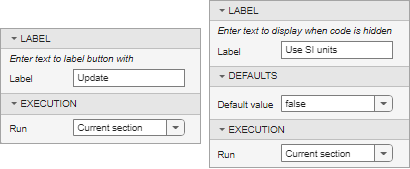

### Hide the Code

To view the example as a dashboard, with the code hidden and only the controls and results visible, go to the **View** tab and click **Hide Code**. Users can now interact with the dashboard by clicking the button to get weather updates and toggling the check box to change units. The Live Editor retrieves and displays weather data based on user-provided inputs.

## Code for Weather Dashboard

This section provides the complete contents of the `WeatherDashboard.mlx` live script file, including the descriptive text, code, and sample output. 

### Weather in Natick, MA

 
data = thingSpeakRead(12397,NumPoints=1000,Timeout=10,OutputFormat='TimeTable');
latestValues = height(data);

useSIUnits = false;

if useSIUnits == 0
    disp("Current conditions: Temperature " + data.TemperatureF(latestValues) + ...
        "F, Humidity " + data.Humidity(latestValues) + "%, Wind " + ...
        data.WindSpeedmph(latestValues) + " mph")
    
    plotWeatherData(data.Timestamps,data.TemperatureF,"F",data.WindSpeedmph, ...
        "mph",data.Humidity)

else
    tempC = (5/9)*(data.TemperatureF-32);
    tempC = round(tempC,2);
    
    windkmh = data.WindSpeedmph*1.60934;
    disp("Current conditions: Temperature " + tempC(latestValues) + "C, Humidity " + ...
        data.Humidity(latestValues) + "%, Wind " + windkmh(latestValues) + "kph")
    
    plotWeatherData(data.Timestamps,tempC,"C",windkmh,"kph",data.Humidity)
end

function plotWeatherData(timestamps,tempData,tempUnits,windData,windUnits,humidityData)
    tiledlayout(3,1);
    
    nexttile
    plot(timestamps,tempData)
    xlabel("Date")
    ylabel("Temp (" + tempUnits + ")")
    title("Temperature (past 1000 data readings)")
    
    nexttile
    plot(timestamps,humidityData)
    xlabel("Date")
    ylabel("Humidity (%)")
    title("Humidity (past 1000 data readings)")
    
    nexttile
    plot(timestamps,windData)
    xlabel("Date")
    ylabel("Wind Speed (" + windUnits + ")")
    title("Wind (past 1000 data readings)")
end

*Copyright 2022 The MathWorks, Inc.*